clear all; close all; clc;

stereoParams = load('raw_data/SP.mat');
stereoParams = stereoParams.stereoParams;

## Under Occlusions

file=dir('raw_data/Stereo_conveyor_with_occlusions/left/*.png');
left = {file.name}';
file=dir('raw_data/Stereo_conveyor_with_occlusions/right/*.png');
right = {file.name}';

for i = 1:1453
    left_name = left(i);
    right_name = right(i);
    l = imread(strcat('raw_data/Stereo_conveyor_with_occlusions/left/',left_name{1}));
    r = imread(strcat('raw_data/Stereo_conveyor_with_occlusions/right/',right_name{1}));
    [im1, im2] = rectifyStereoImages(l, r, stereoParams, "cubic");
    imidx = getNum(i);
    imwrite(im1, 'raw_data/RectifiedImgOcc/left/'+imidx+'.png');
    imwrite(im2, 'raw_data/RectifiedImgOcc/right/'+imidx+'.png');
end

## Without Occlusions

file=dir('raw_data/Stereo_conveyor_without_occlusions/left/*.png');
left = {file.name}';
file=dir('raw_data/Stereo_conveyor_without_occlusions/right/*.png');
right = {file.name}';

for i = 1:1567
    left_name = left(i);
    right_name = right(i);
    l = imread(strcat('raw_data/Stereo_conveyor_without_occlusions/left/',left_name{1}));
    r = imread(strcat('raw_data/Stereo_conveyor_without_occlusions/right/',right_name{1}));
    [im1, im2] = rectifyStereoImages(l, r, stereoParams, "cubic");
    imidx = getNum(i);
    imwrite(im1, 'raw_data/RectifiedImg/left/'+imidx+'.png');
    imwrite(im2, 'raw_data/RectifiedImg/right/'+imidx+'.png');
end

## Draw Epipolar Line

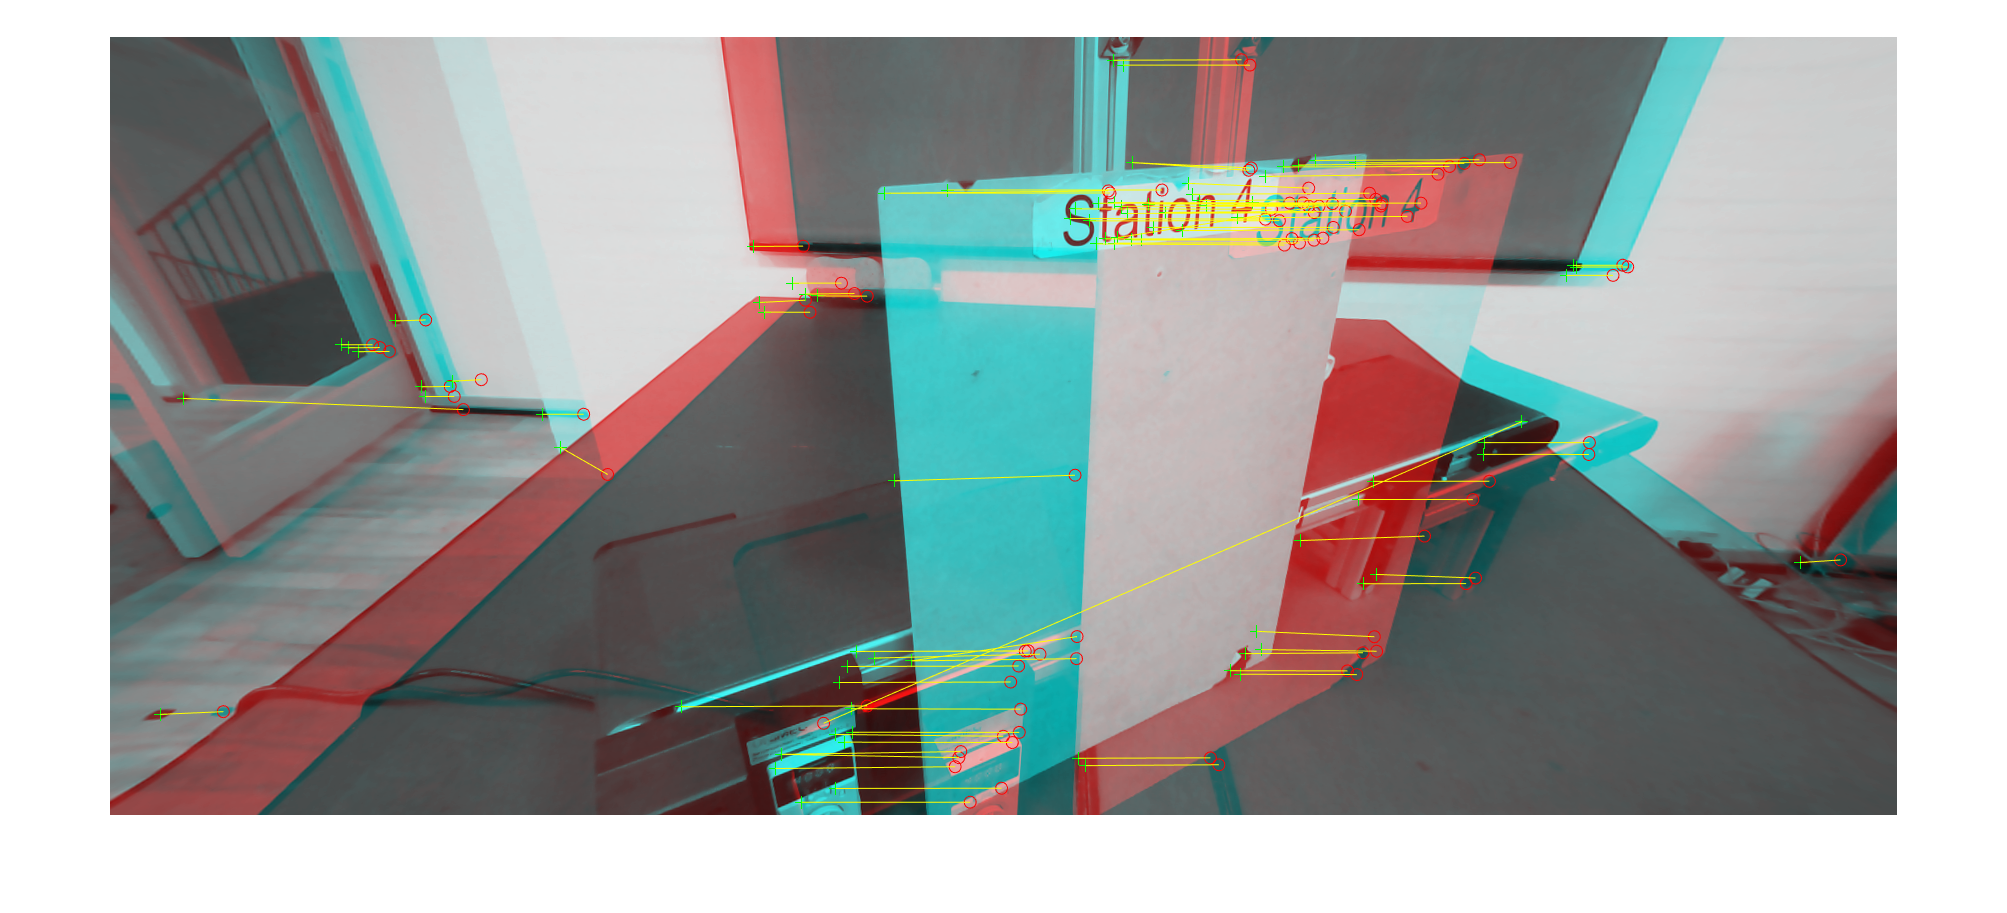

im1 = imread('../raw_data/RectifiedImgOcc/left/1026.png');
im2 = imread('../raw_data/RectifiedImgOcc/right/1026.png');
gray1 = rgb2gray(im1);
gray2 = rgb2gray(im2);
points1 = detectSURFFeatures(gray1);
points2 = detectSURFFeatures(gray2);
[f1,vpts1] = extractFeatures(gray1,points1);
[f2,vpts2] = extractFeatures(gray2,points2);
indexPairs = matchFeatures(f1,f2);
matchedPoints1 = vpts1(indexPairs(1:90,1),:);
matchedPoints2 = vpts2(indexPairs(1:90,2),:);
figure; showMatchedFeatures(im1,im2,matchedPoints1,matchedPoints2);

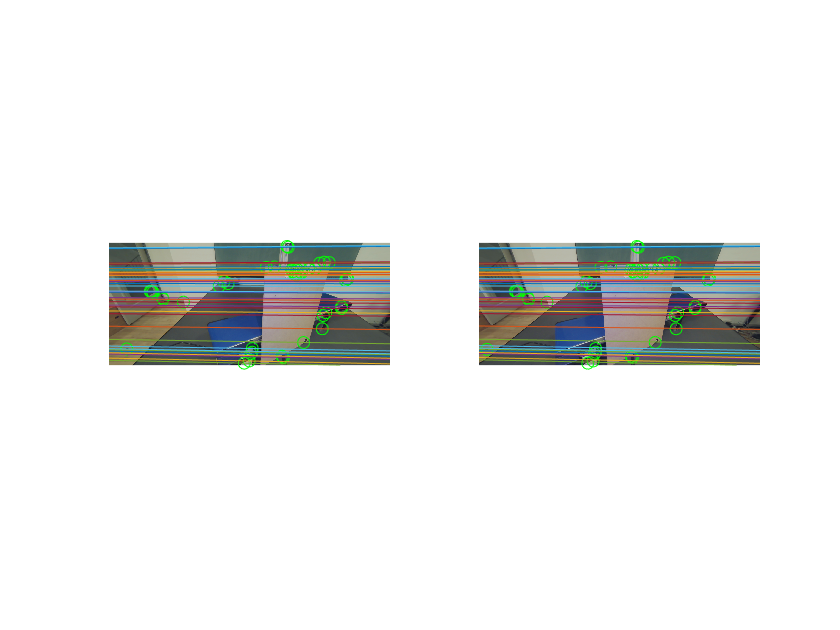

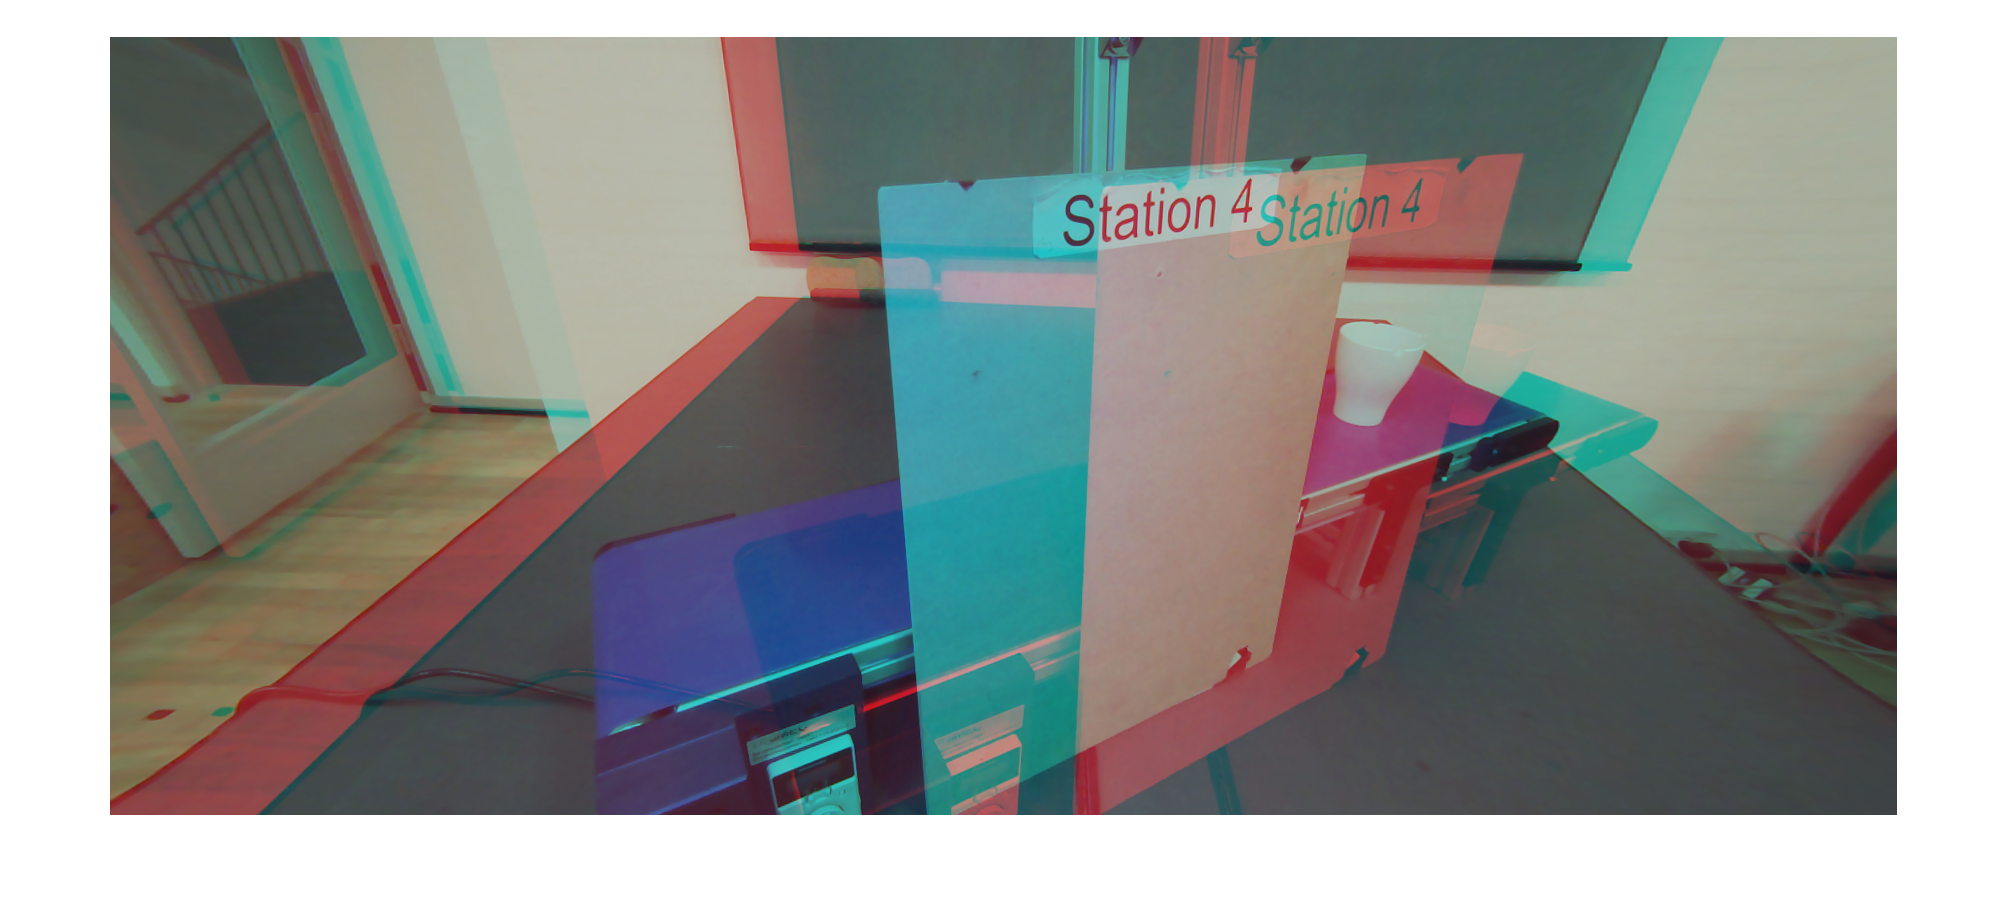

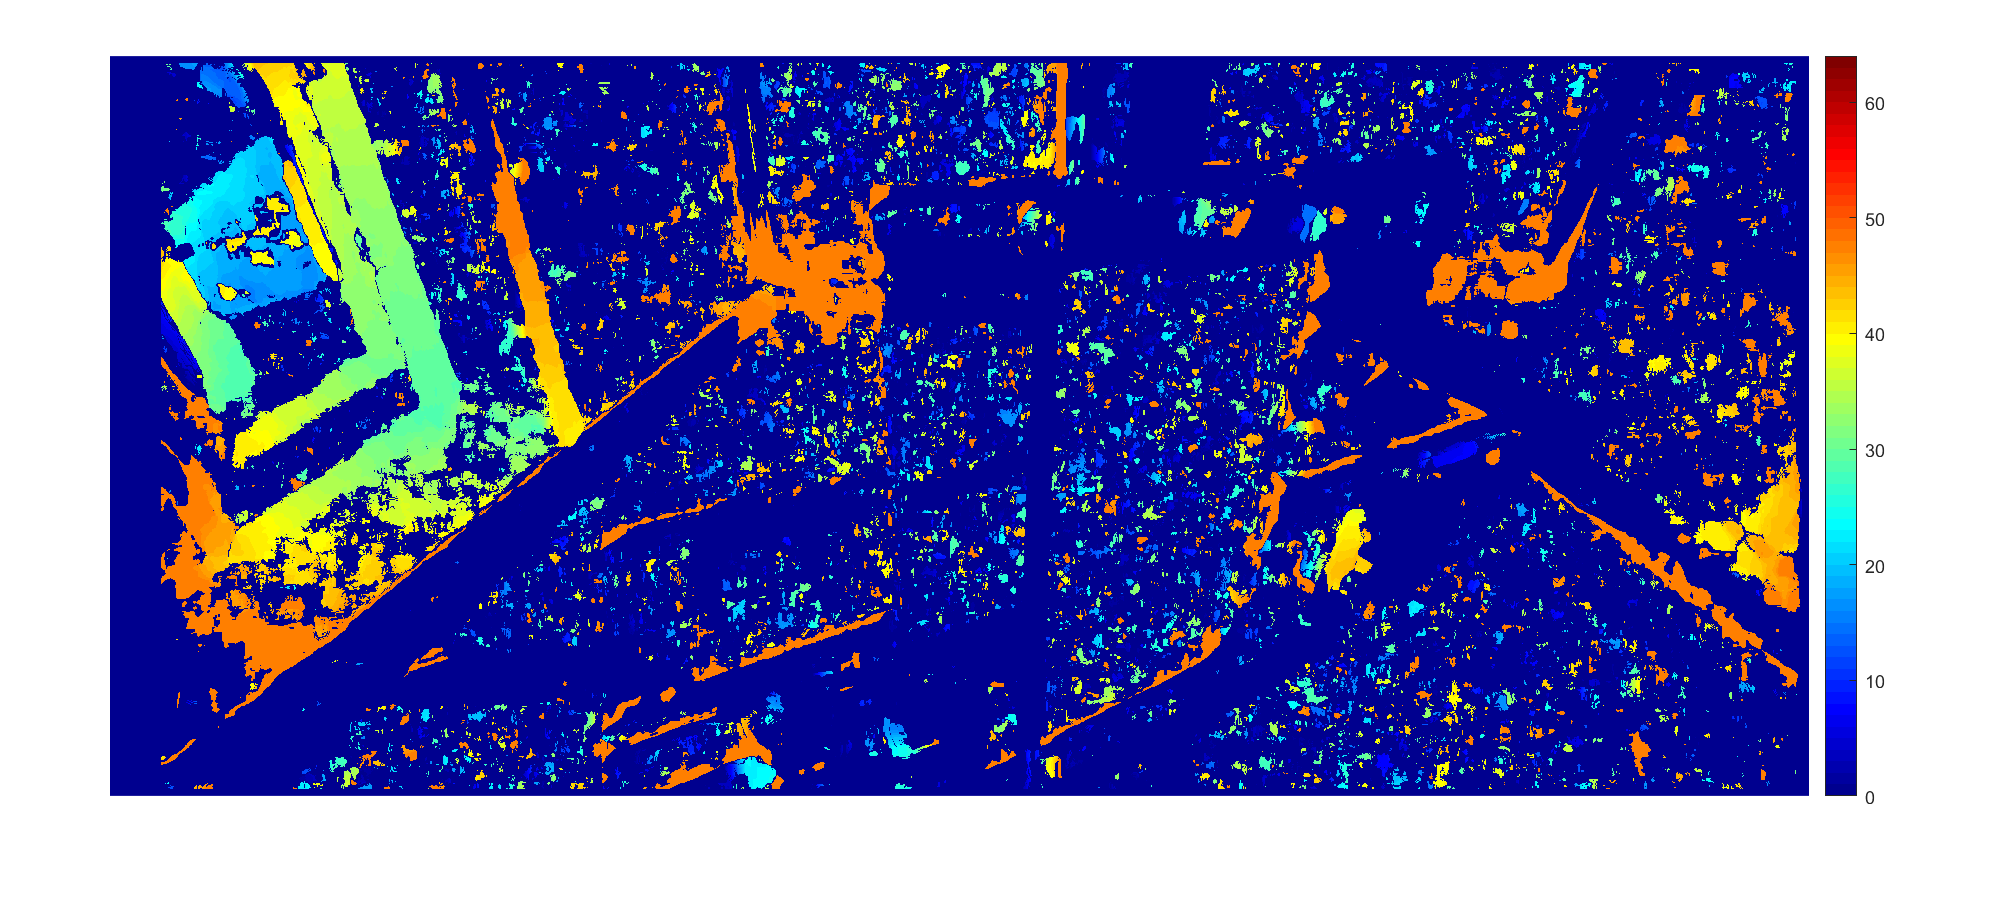

[fLMedS,inliers] = estimateFundamentalMatrix(matchedPoints1,...
    matchedPoints2,'NumTrials',4000);
epiLines = epipolarLine(fLMedS',matchedPoints2.Location(inliers,:));
points = lineToBorderPoints(epiLines,size(gray1));
figure;
subplot(1,2,1)
imshow(im1);
hold on;
plot(matchedPoints1.Location(inliers,1),matchedPoints1.Location(inliers,2),'go')
hold on;
line(points(:,[1,3])',points(:,[2,4])');
subplot(1,2,2)
imshow(im2);
hold on;
plot(matchedPoints2.Location(inliers,1),matchedPoints2.Location(inliers,2),'go')
epiLines = epipolarLine(fLMedS',matchedPoints1.Location(inliers,:));
points = lineToBorderPoints(epiLines,size(gray2));
hold on;
line(points(:,[1,3])',points(:,[2,4])');

function imidx = getNum(i)
th = floor(i/1000);
h = floor(mod(i,1000)/100);
t = floor(mod(i,100)/10);
o = mod(i,10);
imidx = string(th)+string(h)+string(t)+string(o);
end